# Mechatronic Systems Identification Lab 1

## Mikołaj Suchoń

## 1)

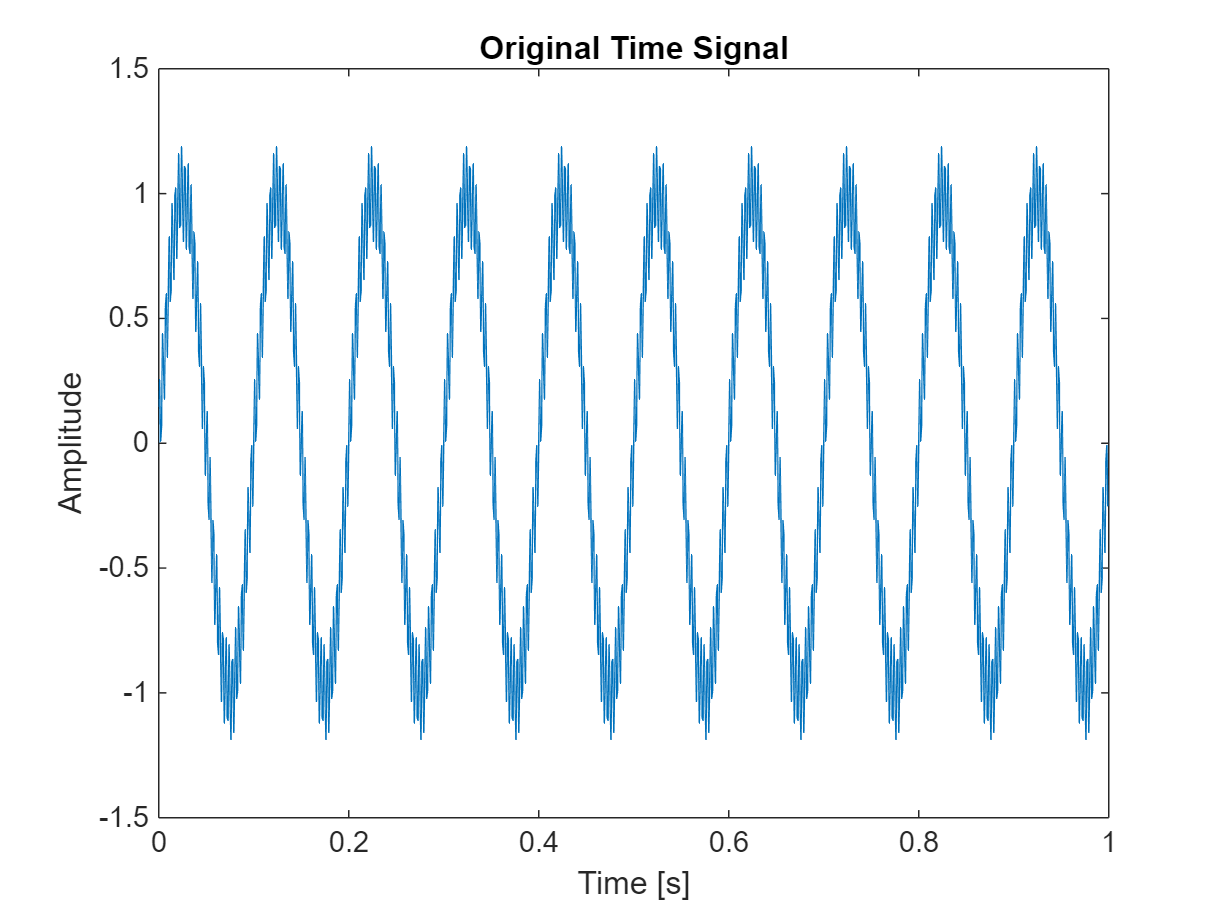

clear

N=1000;
fs=1000;
dt=1/fs;
t=(0:N-1)*dt;
x1=1*sin(2*pi*t*10);
x2=0.2*sin(2*pi*t*300);
y=x1+x2;

plot(t,y);
title('Original Time Signal')
xlabel('Time [s]')
ylabel('Amplitude')


%Windowing
M = 21;                        
h = ones(1, M) / M;            

## Ex.1.1

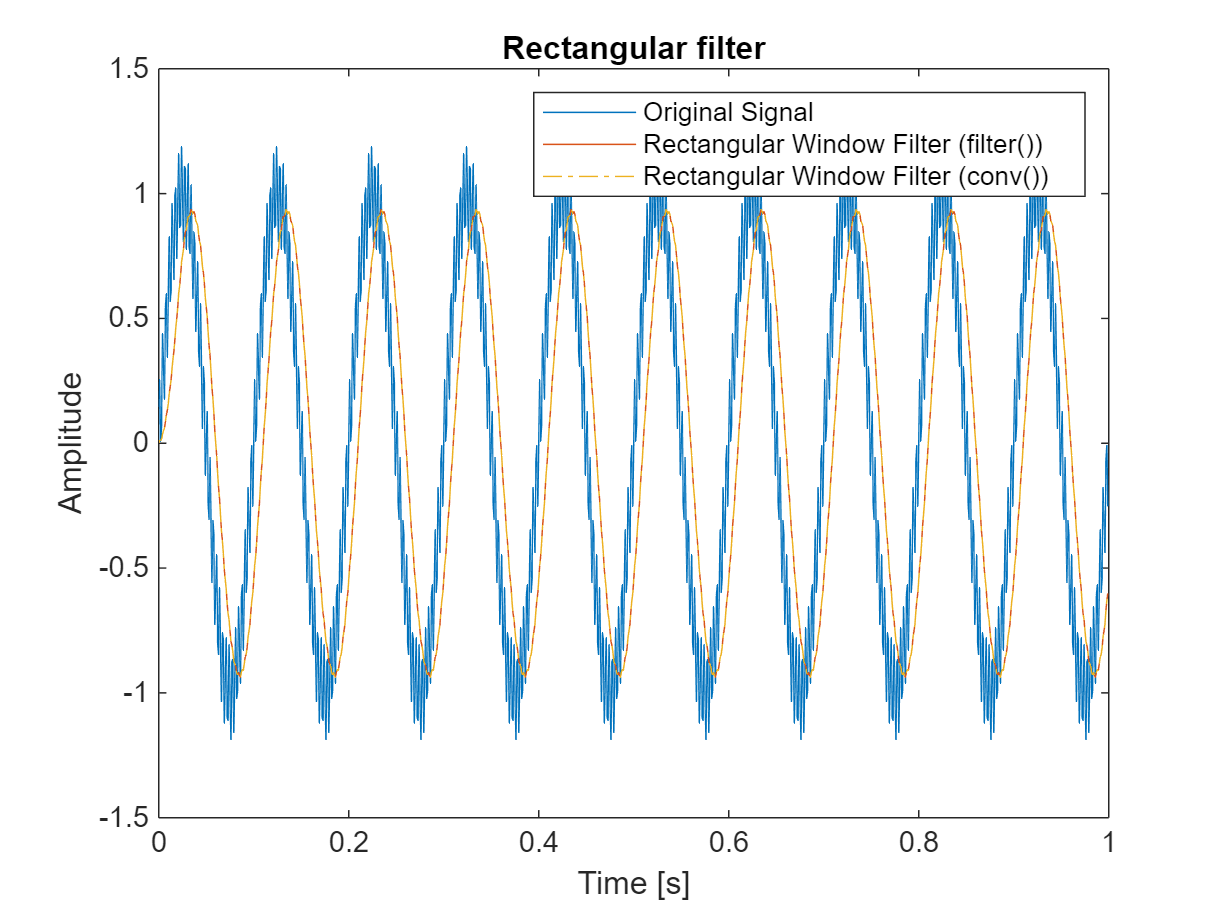

yc = conv(y,h);
yc = yc(1:1000);

Num=h;
yf = filter(Num,1,y);

figure
plot(t,y)
title('Rectangular filter')
hold on
plot(t,yf)
plot(t,yc,'-.')
hold off
xlabel('Time [s]')
ylabel('Amplitude')
legend('Original Signal','Rectangular Window Filter (filter())','Rectangular Window Filter (conv())')

We can see that there is no difference between the conv() function and filter() function, although the signal was correctly filtered.

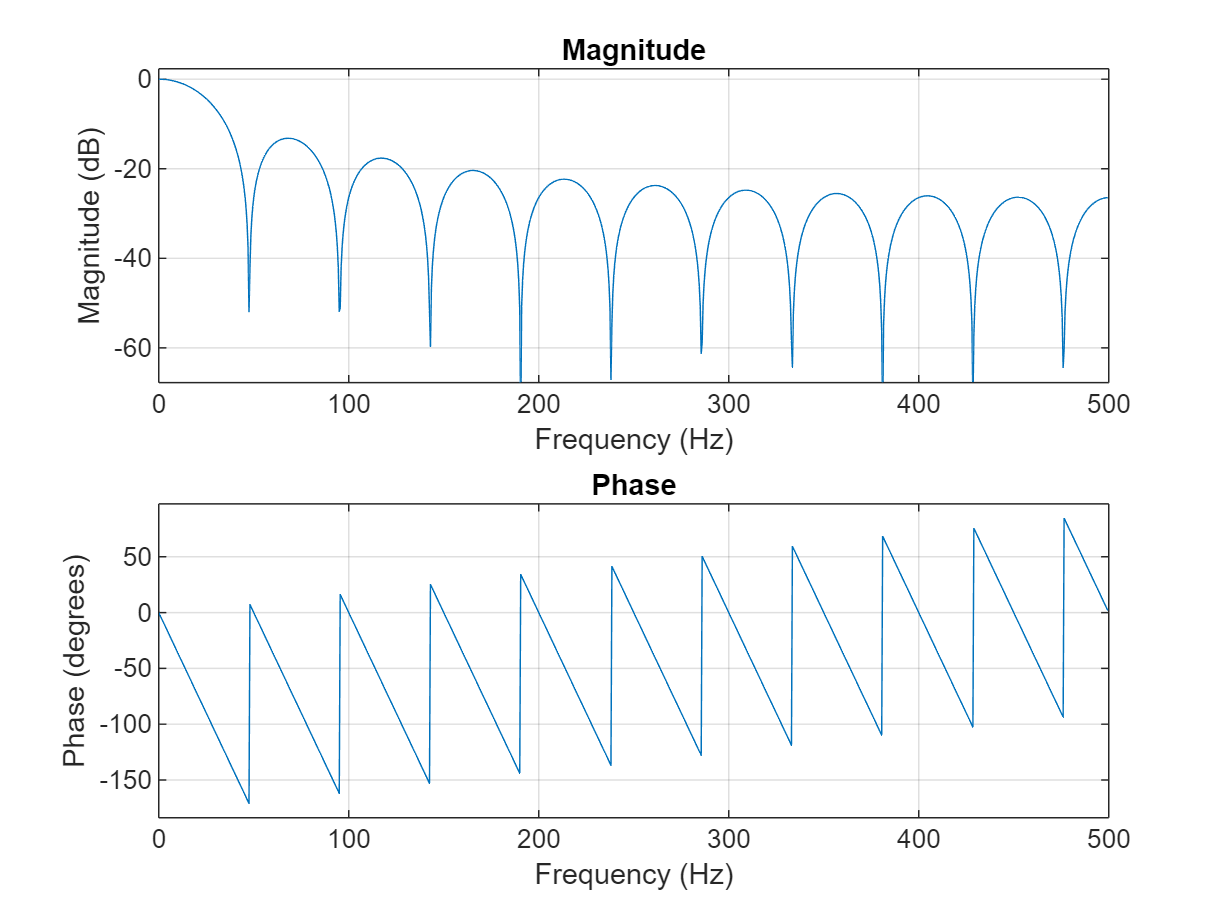

freqz(Num,1,N,fs)

The upside-down peaks (sharp valleys) of the signal frequency lobes show high signal attenuation in between round lobes of lower signal attenuation.

The filter characterisics show high signal attenuation at 100Hz and realtivley low attenuation at lower than 35Hz. This is an example of a digital lowpass filter. 

## Ex.1.2

Apply zero-phase filtering with the filtfilt() function and compare the result with the filter() function. Then try to implement your own method to obtain zero-phase filtering considering the diagram below. Note: the time reversal in Matlab can be written as x(end:-1:1).

Diagram:

H(z)->Time reversal->H(z)->Time reversal

X(z)->X(z)H(z)->X(1/z)H(1/z)->X(1/z)H(1/z)H(z)->X(z)H(z)H(1/z)

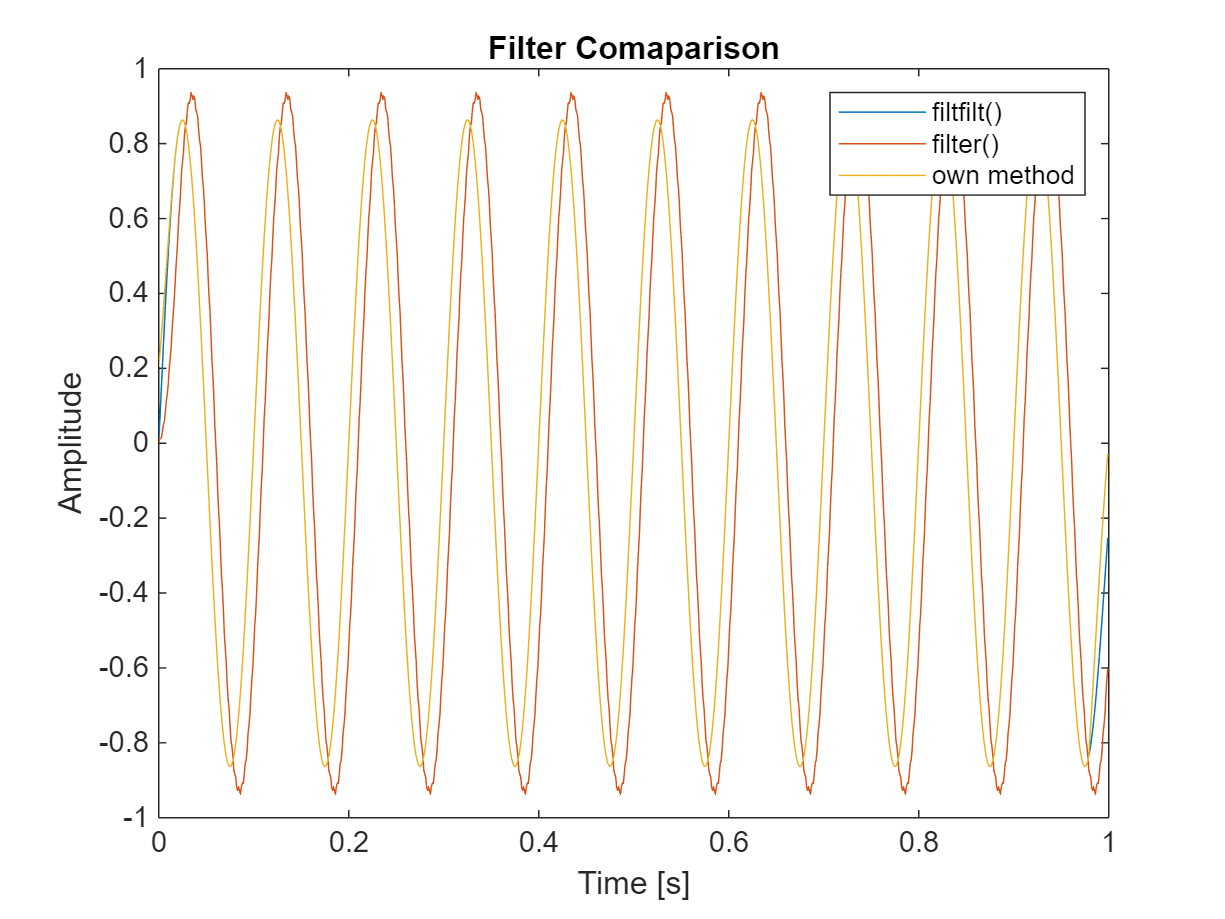

y_filtfilt = filtfilt(h, 1, y);

plot(t,y_filtfilt)
hold on
plot(t,yf)
hold on;
y_manual = filter(h, 1, y);         % Forward filtering
y_manual = flip(y_manual);          % Time reversal
y_manual = filter(h, 1, y_manual);  % Apply filter again
y_manual = flip(y_manual);          % Reverse again to restore original time ord
plot(t,y_manual)
hold off
title('Filter Comaparison')
xlabel('Time [s]')
ylabel('Amplitude')
legend('filtfilt()','filter()','own method')

We observe that the filtfilt() method performs most similar to our own method, deviating only at signal's ends, while te filter() function exibits clear phase shift and magnitude amplification.

## Ex.1.3

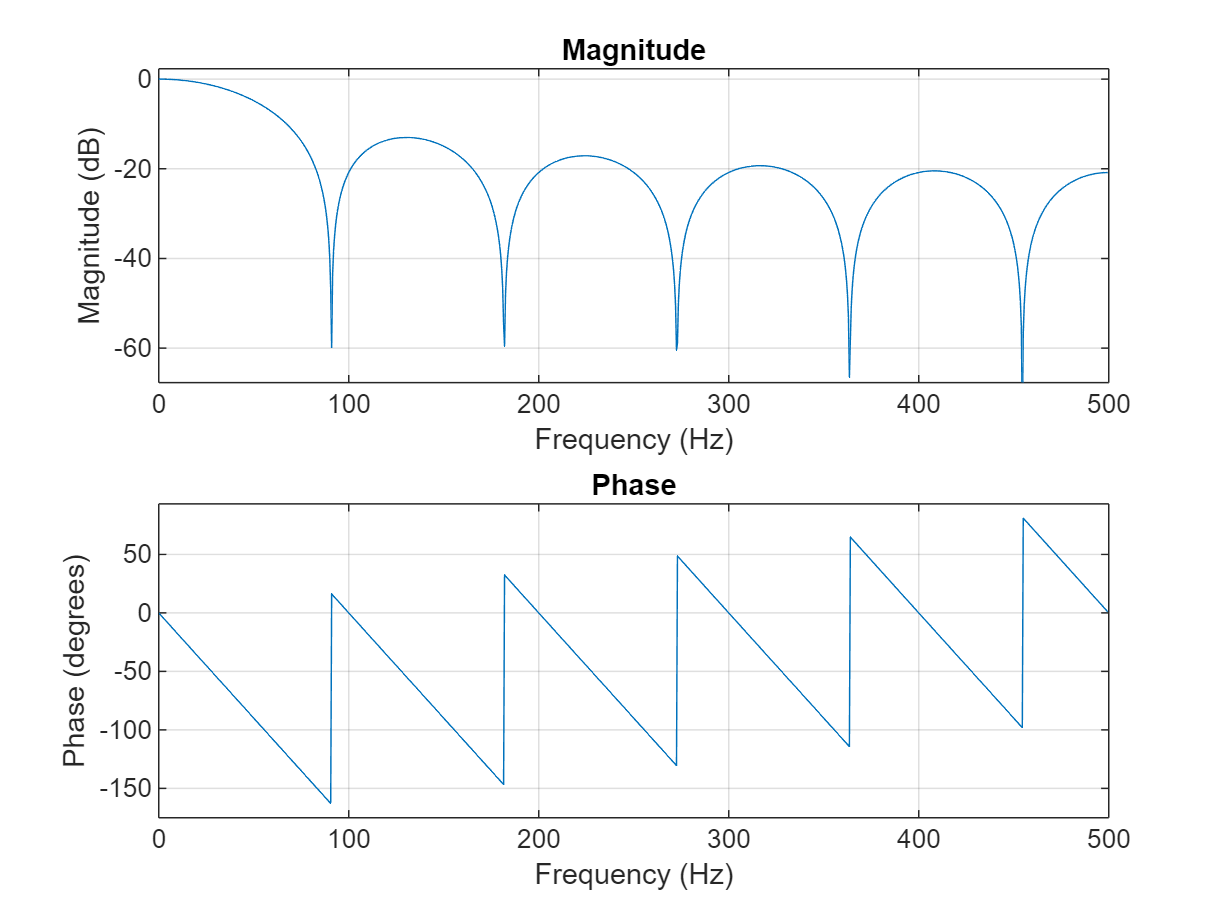

M1 = 11;
M2 = 51;

h1 = ones(1, M1) / M1; 
h2 = ones(1, M2) / M2;

figure;
title('Frequency Response - Rectangular Window (M = 11)');
freqz(h1, 1, N, fs);

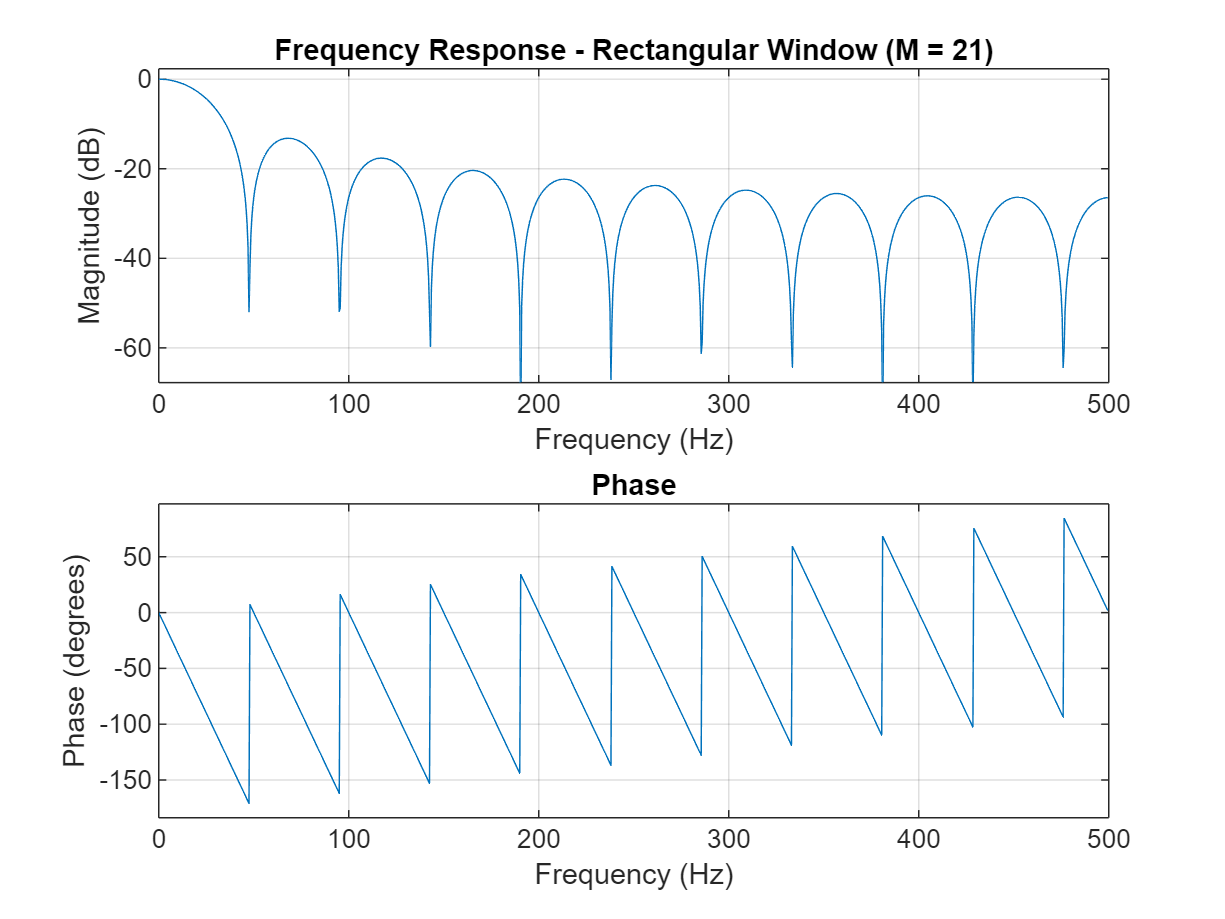


figure
freqz(h, 1, N, fs);
title('Frequency Response - Rectangular Window (M = 21)');

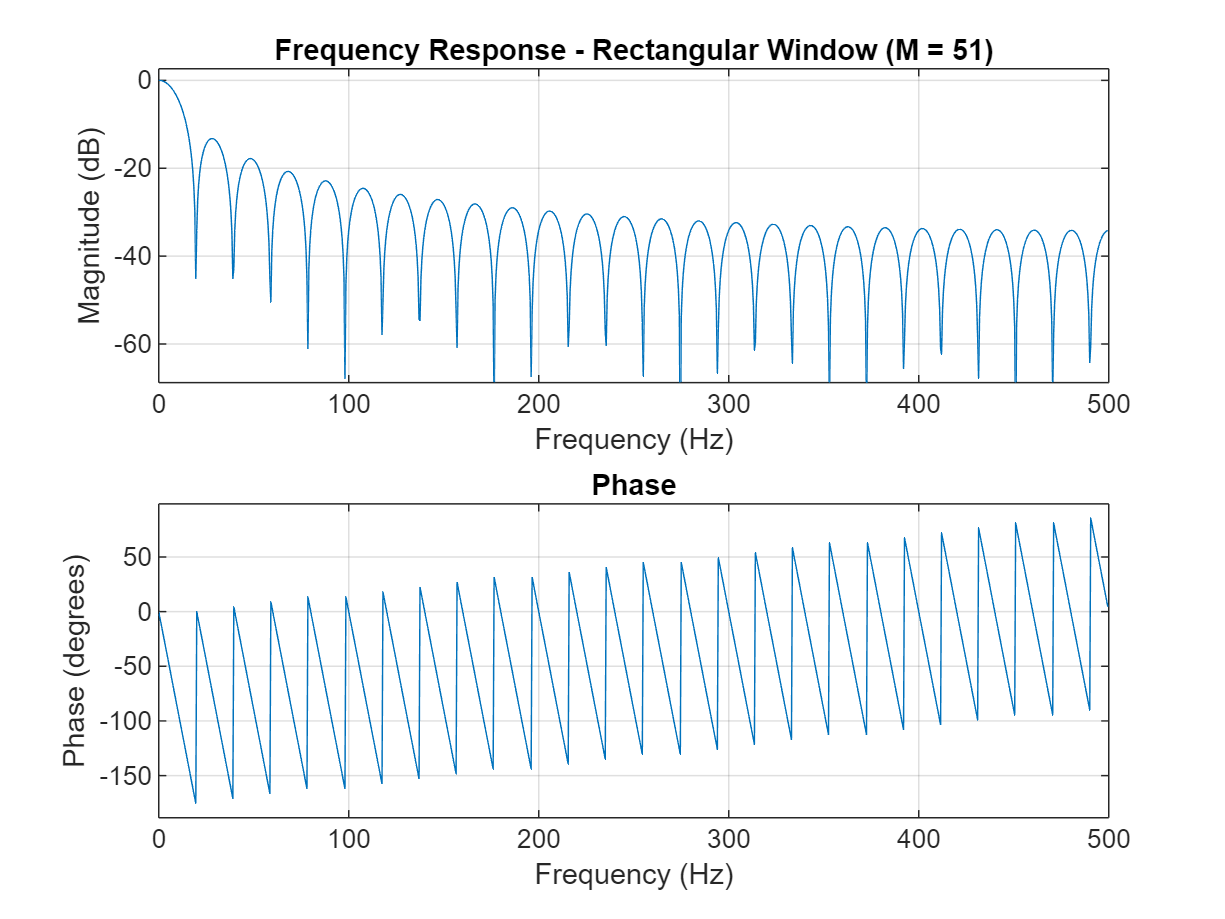


figure
freqz(h2, 1, N, fs);
title('Frequency Response - Rectangular Window (M = 51)');

**Effect of Window Length on Frequency Response:**

- As **window length (M) increases**, the **main lobe becomes narrower**, improving frequency resolution.

- The **-3dB cutoff frequency decreases**, meaning the filter allows **fewer high-frequency components** as M increases.

- **Shorter windows (M = 11)** cause a **wider main lobe** and allow more high-frequency leakage (poorer frequency selectivity).

- **Longer windows (M = 51)** provide **better filtering** by reducing leakage but introduce a slower transient response in time.

## Ex.2

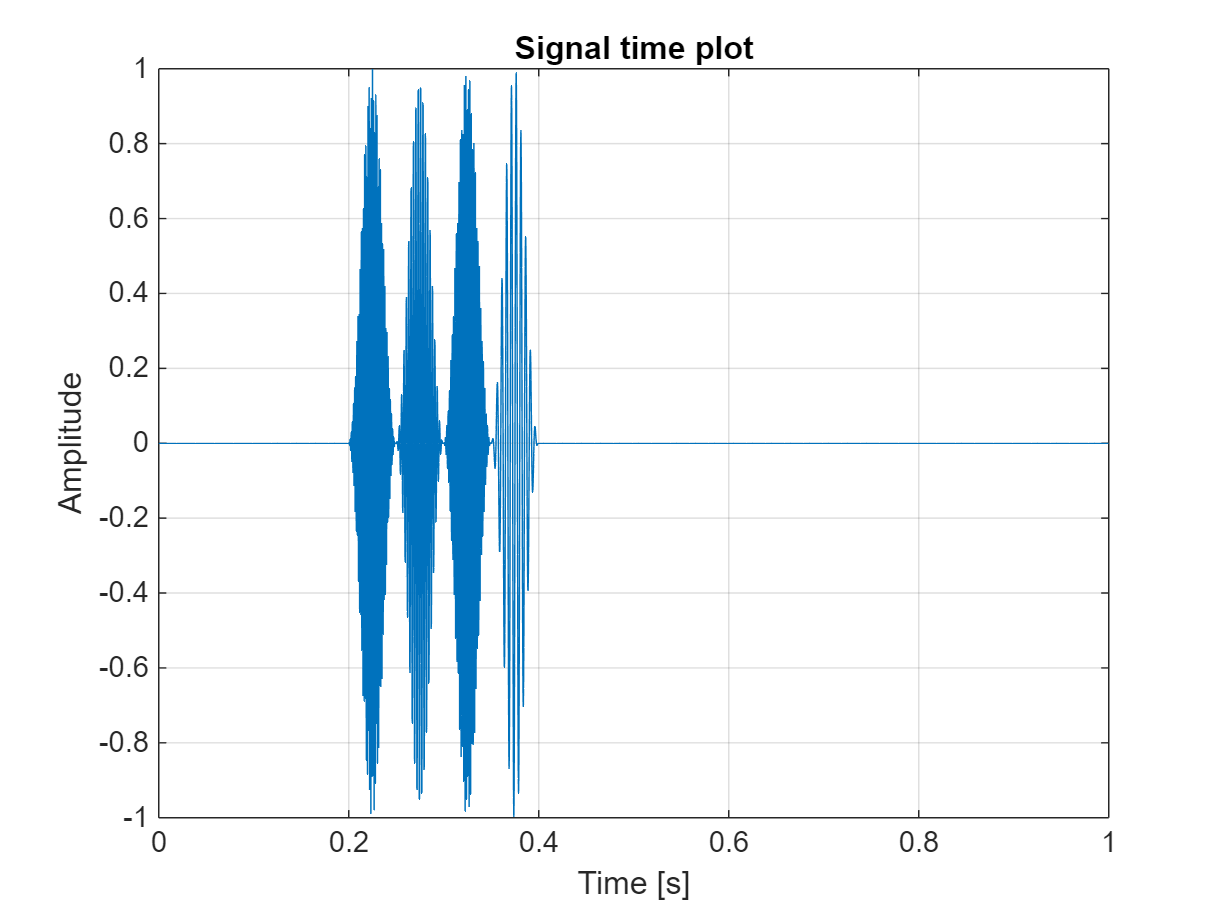

clear
% samping frequency
fs = 4000;
% time duration
tmax = 1-1/fs;
% time vector
t = 0:1/fs:tmax;
s = length(t);
% frequency vector
f = linspace(0,fs-fs/s,s);
% centra lfrequency of sine waves
w = [200,400,700,850];
% hann window 200 samples
mask = hann(200);
% time delay of the signals
inds = [1400,1000,1200,800];
% allocare memory for y
y = zeros(length(t),1);
% add sine waves
for i = 1:length(w)
m = zeros(s,1);
m(inds(i):inds(i)+length(mask)-1) = mask;
y_temp = sin(2*pi*t*w(i)).*m.';
y = y+y_temp.';
end
plot(t,y)
grid on;
title('Signal time plot')
xlabel('Time [s]')
ylabel('Amplitude')


Hd = Filter();
y_filtered=Hd(y);

Hd2 = Filter2();

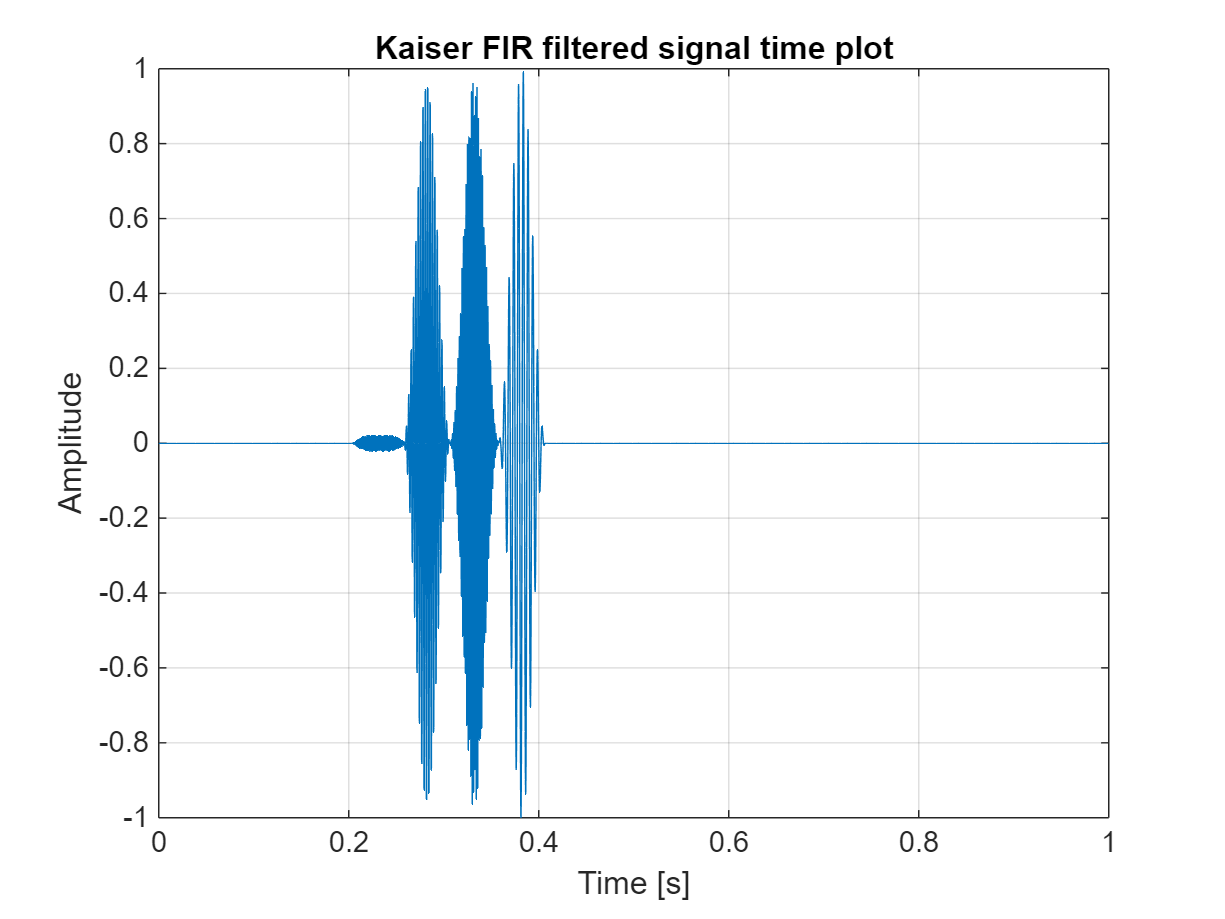

y_filtered2=Hd2(y);

plot(t,y_filtered)
grid on;
title('Kaiser FIR filtered signal time plot')
xlabel('Time [s]')
ylabel('Amplitude')

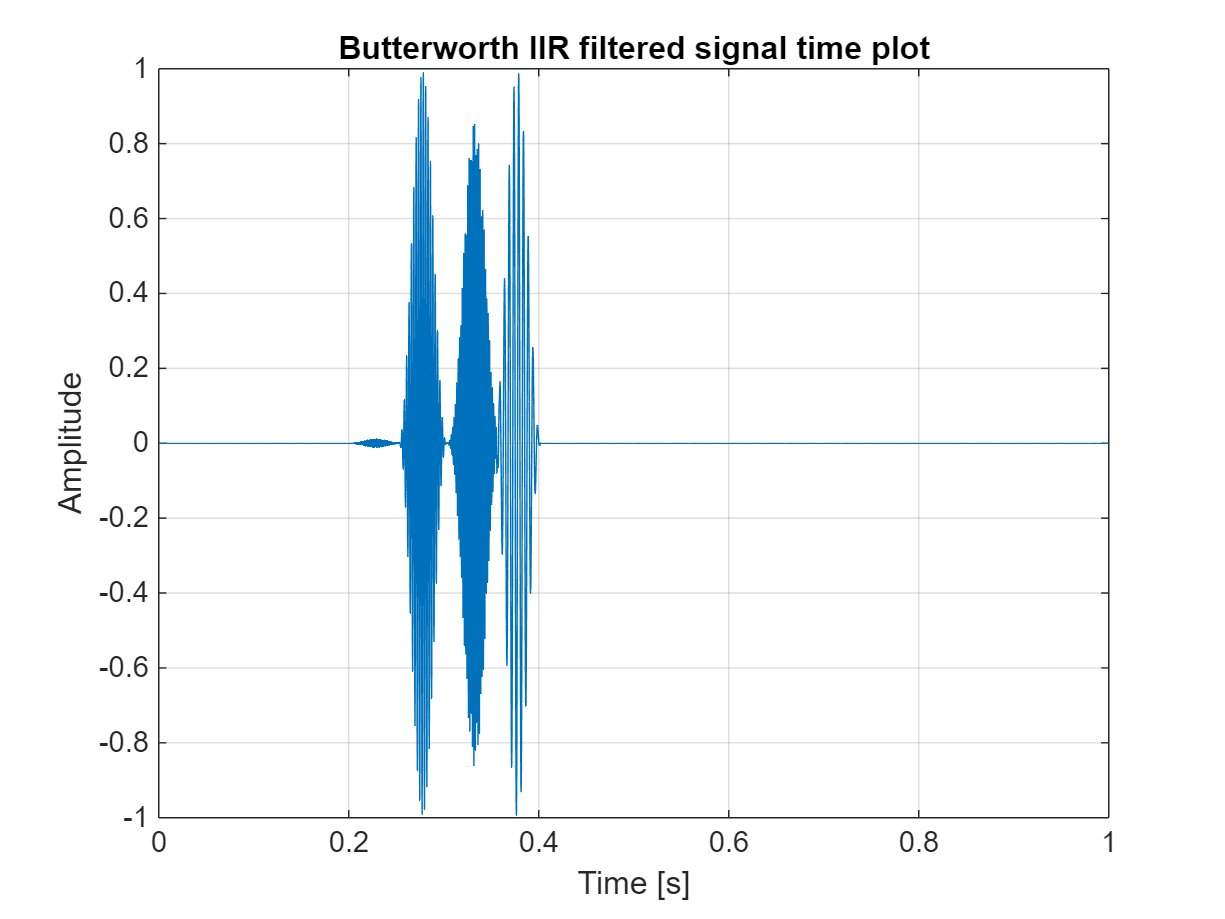


plot(t,y_filtered2)
grid on;
title('Butterworth IIR filtered signal time plot')
xlabel('Time [s]')
ylabel('Amplitude')

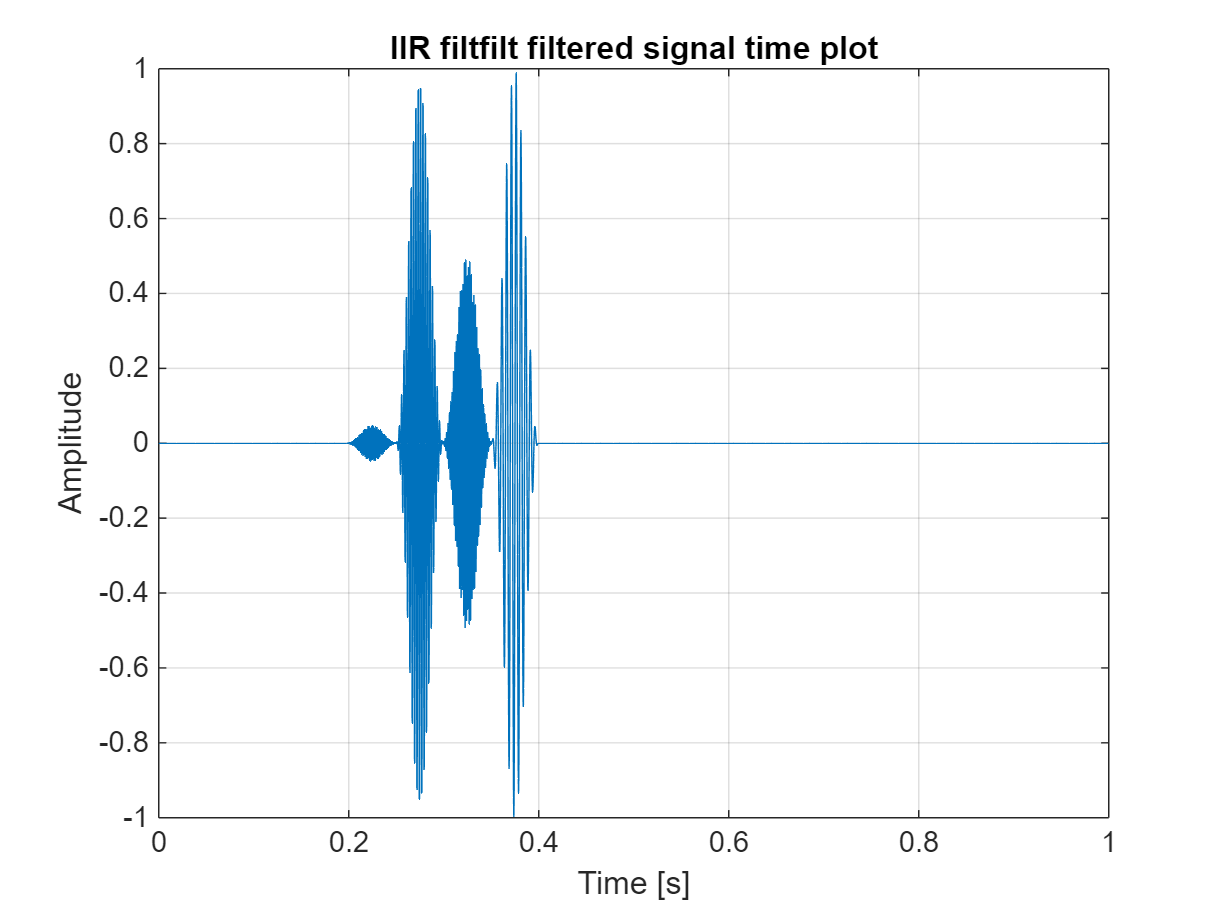


y_manual2 = step(Hd2, y);        % Forward filtering
y_manual2 = flip(y_manual2);     % Time reversal
y_manual2 = step(Hd2, y_manual2);% Apply filter again
y_manual2 = flip(y_manual2);     % Reverse again

[b, a] = butter(6, 700/(fs/2), 'low'); % Get IIR coefficients
y_filt = filtfilt(b, a, y); % Zero-phase filtering

plot(t,y_filt)
grid on;
title('IIR filtfilt filtered signal time plot')
xlabel('Time [s]')
ylabel('Amplitude')

order(Hd) 

ans = 60

order(Hd2)

ans = 21

We can observe here that the order of the FIR filter is close to three times higher than the order of the IIR filter (60 vs 21). This means that the FIR is more computationally costly but have **linear phase**, meaning they do not distort phase relationships.

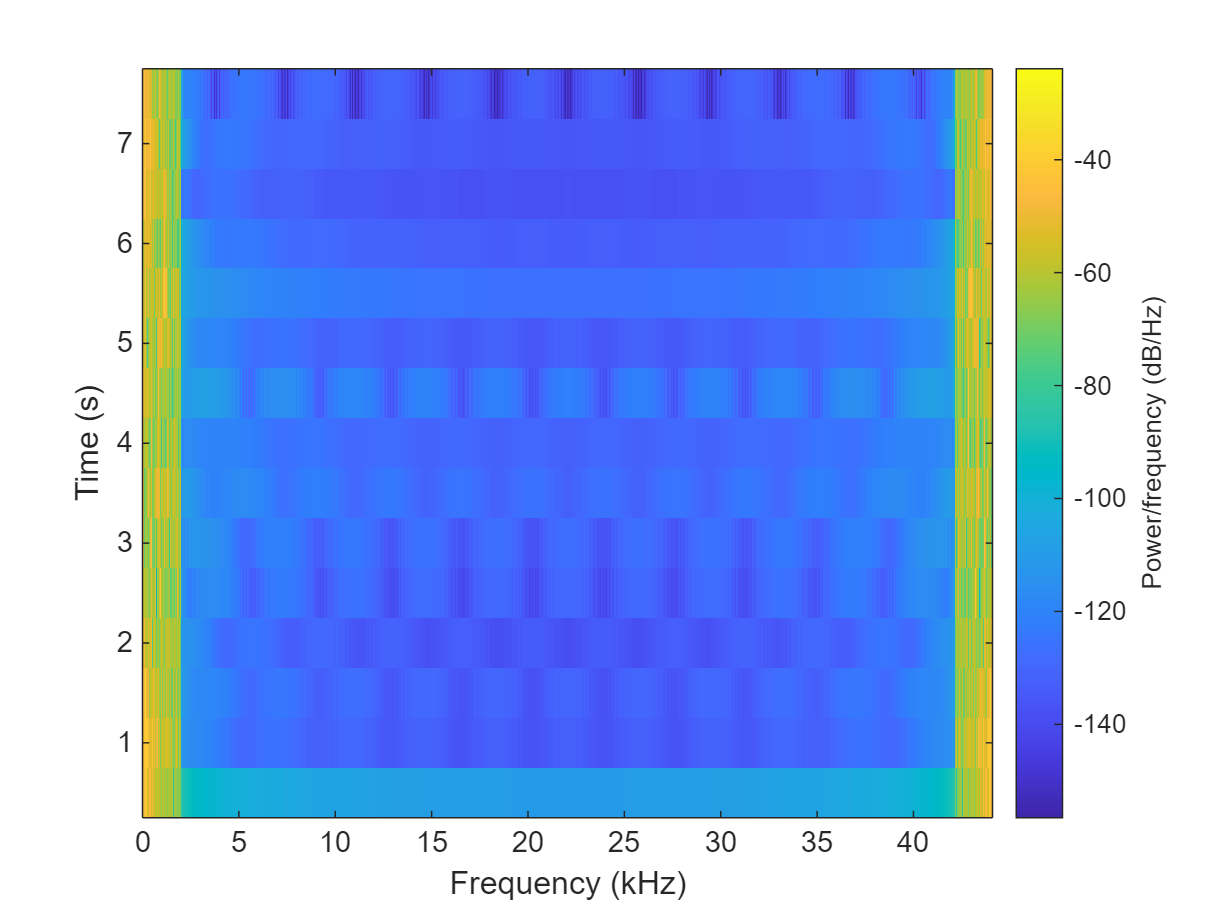

clear
[data,fs] = audioread('ktoto.wav');

dt=1/fs;
N=length(data);
t=(0:N-1)*dt;
df=fs/N;
fv = (0:N-1)*df; % frequency vector
% sound(data(:,1), fs)
y=data(:,1);

[y,Y]=Filter_signal_LP(data(:,1),fs,2000);

% sound(real(y), fs)
window=1*fs;
noverlap=2*fs*0.25;
figure
spectrogram(y,window,noverlap,fv,fs)

This filtration method allows for the signal to eliminate most of the noise allowing us to hear the iconic line form 'Lord of the Rings' clearly.

The actor speaking is clearly Dumbeldore :)

function Hd = Filter
%FILTER Returns a discrete-time filter object.

% MATLAB Code
% Generated by MATLAB(R) 9.14 and DSP System Toolbox 9.16.
% Generated on: 20-Mar-2025 11:03:14

% FIR Window Lowpass filter designed using the FIR1 function.

% All frequency values are in Hz.
Fs = 4000;  % Sampling Frequency

Fpass = 700;             % Passband Frequency
Fstop = 850;             % Stopband Frequency
Dpass = 0.057501127785;  % Passband Ripple
Dstop = 0.01;            % Stopband Attenuation
flag  = 'scale';         % Sampling Flag

% Calculate the order from the parameters using KAISERORD.
[N,Wn,BETA,TYPE] = kaiserord([Fpass Fstop]/(Fs/2), [1 0], [Dstop Dpass]);

% Calculate the coefficients using the FIR1 function.
b  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);
Hd = dsp.FIRFilter( ...
    'Numerator', b);

% [EOF]
 
end

function Hd = Filter2
%GETFILTER Returns a discrete-time filter System object.

% MATLAB Code
% Generated by MATLAB(R) 9.14 and DSP System Toolbox 9.16.
% Generated on: 22-Mar-2025 11:53:07

Fpass = 700;   % Passband Frequency
Fstop = 850;   % Stopband Frequency
Apass = 1;     % Passband Ripple (dB)
Astop = 40;    % Stopband Attenuation (dB)
Fs    = 4000;  % Sampling Frequency

h = fdesign.lowpass('fp,fst,ap,ast', Fpass, Fstop, Apass, Astop, Fs);

Hd = design(h, 'butter', ...
    'MatchExactly', 'stopband', ...
    'SystemObject', true,...
    UseLegacyBiquadFilter=true);

end

function [x,X] = Filter_signal_LP(x,fs,cutoff)

x  = x(:);                          % force colums vector
N  = length(x);
df = fs/N;
cuoff_index = ceil(cutoff/df);

X = fft(x);

X(1)                       = 0;    % Remove DC component
X(cuoff_index:end-cuoff_index) = 0;
X(end)=0;

x = ifft(X);
end